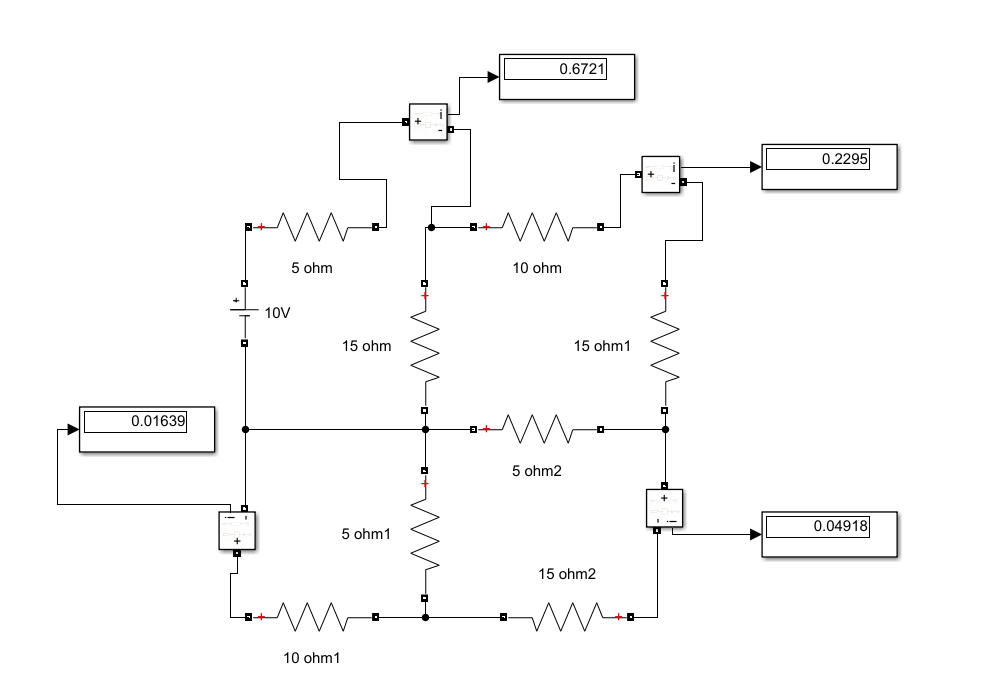

clc;
clear;
format short;
tic();
A = [ 20 -15 0 0; -15 45 0 -5; 0 0 15 -5; 0 -5 -5 25 ];
B = [10; 0; 0; 0];
if(det(A)==0)
    disp('Determinant is 0, so unable to proceed')
    return;
end

answer = A\B;

aug = [A,B]; % Augmented Matrix

n = length(A)

n = 4

for i = 1:n-1
    fprintf('i=%d,',i)
    for j = 1:(n-i)
        if(aug(i,i)==0)
            disp(' Divided by 0 Error was coming thats why, I returned from here ');
            return; % This is added 
        end
        alpha = aug(j+i,i)/aug(i,i);
        aug(j+i,:) = aug(j+i,:) - alpha*aug(i,:);
    end
end

i=1,i=2,i=3,


disp(aug); % Converted into upper triangular Matrix

   20.0000  -15.0000         0         0   10.0000
         0   33.7500         0   -5.0000    7.5000
         0         0   15.0000   -5.0000         0
         0         0         0   22.5926    1.1111




% Doing Backsubstitution

xvalues(1:length(A)) = 0; % Creates X values
xvalues = xvalues';
for i = 1:length(xvalues)
    index = length(xvalues)-i+1;
    xvalues(index) = (aug(index,end) - aug(index,index:length(xvalues))*xvalues(index:length(xvalues)))/aug(index,index);
end

disp('Final Values = ')

Final Values = 


disp(xvalues);

    0.6721
    0.2295
    0.0164
    0.0492



disp('Correct Ans = ');

Correct Ans = 


disp(answer);

    0.6721
    0.2295
    0.0164
    0.0492



toc();

Elapsed time is 0.768003 seconds.
